clc;clear;

data_part1 = readtable('data_part_1.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data_part1.Properties.VariableNames{1} = 'SampleID';
data_part1.SampleID = strcat('part1_', string(data_part1.SampleID));


data_part1_numbers = length(data_part1.SampleID);

data_part1_trait_names = data_part1.Properties.VariableNames(2:21);
data_part1_trait_numbers = length(data_part1_trait_names);
data_part1_wave_lengths = str2double(data_part1.Properties.VariableNames(22:end));
data_part1_wave_numbers = length(data_part1_wave_lengths);


data_part2 = readtable('data_part_2.csv', 'ReadVariableNames', true, 'VariableNamingRule','preserve');
data_part2.Properties.VariableNames{1} = 'SampleID';
data_part2.SampleID = strcat('part2_', string(data_part2.SampleID));

data_part2_numbers = length(data_part2.SampleID);

data_part2_numbers = 1115


data_part2_trait_names = data_part2.Properties.VariableNames(2:38);
data_part2_trait_numbers = length(data_part2_trait_names);
data_part2_wave_lengths = str2double(data_part2.Properties.VariableNames(39:end));
data_part2_wave_numbers = length(data_part2_wave_lengths);

[common_traits, idx1, idx2] = intersect(data_part1_trait_names, data_part2_trait_names);

if isequal(data_part1_wave_lengths, data_part2_wave_lengths)
    disp('two wave_lengths are same');
else
    disp('two wave_lengths are not same');
end

two wave_lengths are same



wave_lengths_common = data_part1_wave_lengths;
wave_numbers_common = data_part2_wave_numbers;


data_part1_common = data_part1(:, [{'SampleID'}, common_traits]);
data_part2_common = data_part2(:, [{'SampleID'}, common_traits]);
common_traits_numbers = length(common_traits);

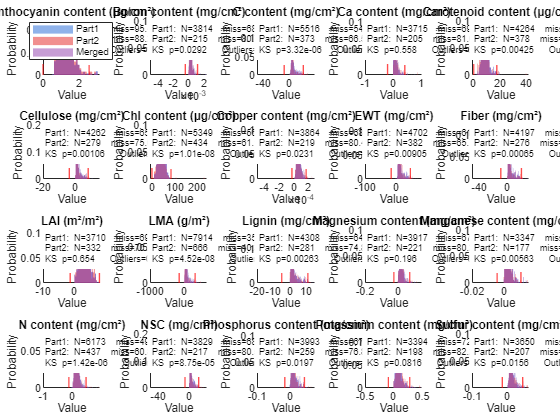

Trait Anthocyanin content (μg/cm²): Part1 NaN=11614, Part2 NaN=983
Trait Boron content (mg/cm²): Part1 NaN=8366, Part2 NaN=900
Trait C content (mg/cm²): Part1 NaN=6664, Part2 NaN=742
Trait Ca content (mg/cm²): Part1 NaN=8465, Part2 NaN=910
Trait Carotenoid content (μg/cm²): Part1 NaN=7916, Part2 NaN=737
Trait Cellulose (mg/cm²): Part1 NaN=7918, Part2 NaN=836
Trait Chl content (μg/cm²): Part1 NaN=6831, Part2 NaN=681
Trait Copper content (mg/cm²): Part1 NaN=8316, Part2 NaN=896
Trait EWT (mg/cm²): Part1 NaN=7478, Part2 NaN=733
Trait Fiber (mg/cm²): Part1 NaN=7983, Part2 NaN=839
Trait LAI (m²/m²): Part1 NaN=8470, Part2 NaN=783
Trait LMA (g/m²): Part1 NaN=4266, Part2 NaN=449
Trait Lignin (mg/cm²): Part1 NaN=7872, Part2 NaN=834
Trait Magnesium content (mg/cm²): Part1 NaN=8263, Part2 NaN=894
Trait Manganese content (mg/cm²): Part1 NaN=8833, Part2 NaN=938
Trait N content (mg/cm²): Part1 NaN=6007, Part2 NaN=678
Trait NSC (mg/cm²): Part1 NaN=8351, Part2 NaN=898
Trait Phosphorus content (mg/cm²):

% trait distribution of three dataset
trait_names   = common_traits;
trait_numbers = numel(trait_names);

% color for three dataset
c1 = [0.20 0.45 0.85];
c2 = [0.9 0.2 0.2];
c3 = [0.6 0.3 0.7];

figure; 
clf;
tiledlayout(4,5, "TileSpacing","compact","Padding","compact");

for j = 1:trait_numbers
    % remove NaN
    x1 = table2array(data_part1_common(:, trait_names(j)));
    x2 = table2array(data_part2_common(:, trait_names(j)));
    nNaN1 = sum(isnan(x1));
    nNaN2 = sum(isnan(x2));
    fprintf('Trait %s: Part1 NaN=%d, Part2 NaN=%d\n', string(trait_names(j)), nNaN1, nNaN2);
    x1 = x1(~isnan(x1));
    x2 = x2(~isnan(x2));

    % use the merged data to compute common binning.
    x_all = [x1; x2];
    if isempty(x_all) || numel(unique(x_all))==1
        minx = min([x_all; 0]); maxx = max([x_all; 1]);
        edges = linspace(minx-0.5, maxx+0.5, 5);
    else
        [~, edges] = histcounts(x_all, 'BinMethod','fd');
        if numel(edges) < 3
            edges = linspace(min(x_all), max(x_all), 11);
        end
    end

    nexttile; 
    hold on;

    % histogram
    h1 = histogram(x1, 'Normalization','probability', 'BinEdges',edges, ...
                   'EdgeColor','none', 'FaceColor',c1, 'FaceAlpha',0.55);
    h2 = histogram(x2, 'Normalization','probability', 'BinEdges',edges, ...
                   'EdgeColor','none', 'FaceColor',c2, 'FaceAlpha',0.55);
    h3 = histogram(x_all, 'Normalization','probability', 'BinEdges',edges, ...
                   'EdgeColor','none', 'FaceColor',c3, 'FaceAlpha',0.55);

    % mean and std on merged data
    mu_all = mean(x_all,'omitnan');
    sigma_all = std(x_all,0,'omitnan');

    % ±3σ lines
    xline(mu_all - 3*sigma_all, '--r', 'LineWidth', 1);
    xline(mu_all + 3*sigma_all, '--r', 'LineWidth', 1);

    % label
    ylabel('Probability');
    xlabel('Value');
    title(string(trait_names(j)), 'Interpreter','none');

    % statistics
    n1 = numel(x1);
    n2 = numel(x2);
    miss1 = 1 - n1 / data_part1_numbers;
    miss2 = 1 - n2 / data_part2_numbers;
    m1 = mean(x1, 'omitnan'); s1 = std(x1, 'omitnan');
    m2 = mean(x2, 'omitnan'); s2 = std(x2, 'omitnan');

    % KS test
    pval = NaN;
    if n1>0 && n2>0
        try
            [~, pval] = kstest2(x1, x2);
        catch
            % pass
        end
    end
    
    outlier_numbers = sum(abs((x_all - mu_all)./sigma_all) > 3);
    
    % note
    note = sprintf([ ...
        'Part1: N=%d  miss=%.1f%%  \\mu=%.3g  \\sigma=%.3g\n' ...
        'Part2: N=%d  miss=%.1f%%  \\mu=%.3g  \\sigma=%.3g\n' ...
        'KS p=%.3g   Outliers=%d'], ...
        n1, miss1*100, m1, s1, ...
        n2, miss2*100, m2, s2, ...
        pval, outlier_numbers);
    
    text(0.02, 0.95, note, ...
        'Units','normalized', ...  
        'VerticalAlignment','top', ...
        'FontSize',7, ...
        'BackgroundColor',[1 1 1 0.75], ...
        'Margin',3, ...
        'Interpreter','tex');
    
    % legend
    if j == 1
        legend([h1 h2 h3], {'Part1','Part2','Merged'}, 'Location','best');
    end

    hold off;
end

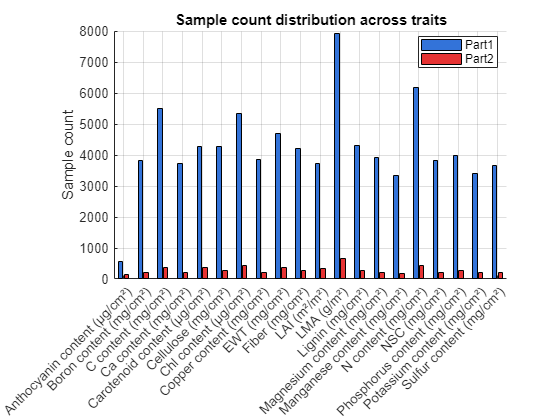


% sample count distribution across traits

n1_all = zeros(trait_numbers,1);
n2_all = zeros(trait_numbers,1);

for j = 1:trait_numbers
    x1 = table2array(data_part1_common(:, trait_names(j)));
    x2 = table2array(data_part2_common(:, trait_names(j)));
    n1_all(j) = sum(~isnan(x1));
    n2_all(j) = sum(~isnan(x2));
end

figure; 
clf; 
hold on;
b = bar([n1_all n2_all], 'grouped');
b(1).FaceColor = c1;
b(2).FaceColor = c2;

set(gca,'XTick',1:trait_numbers,'XTickLabel',trait_names, ...
    'XTickLabelRotation',45);
ylabel('Sample count');
title('Sample count distribution across traits');
legend({'Part1','Part2'}, 'Location','best');
grid on;

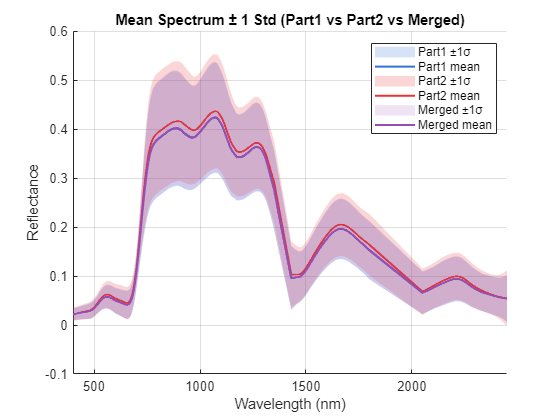

% spectra distribution of three dataset

% part1
spectra_data1 = table2array(data_part1(:,22:end));
mean_spectra1 = mean(spectra_data1, 1, 'omitnan');
std_spectra1  = std(spectra_data1, 0, 1, 'omitnan');

% part2
spectra_data2 = table2array(data_part2(:,39:end));
mean_spectra2 = mean(spectra_data2, 1, 'omitnan');
std_spectra2  = std(spectra_data2, 0, 1, 'omitnan');

% merged
spectra_all = [spectra_data1; spectra_data2];
mean_spectra_all = mean(spectra_all, 1, 'omitnan');
std_spectra_all = std(spectra_all, 0, 1, 'omitnan');

figure; 
clf; 
hold on;

% part1 mean and std line
fill([wave_lengths_common fliplr(wave_lengths_common)], ...
     [mean_spectra1-std_spectra1, fliplr(mean_spectra1+std_spectra1)], ...
     c1, 'FaceAlpha', 0.20, 'EdgeColor', 'none');
plot(wave_lengths_common, mean_spectra1, 'Color', c1, 'LineWidth', 1.5);

% part2 mean and std line
fill([wave_lengths_common fliplr(wave_lengths_common)], ...
     [mean_spectra2-std_spectra2, fliplr(mean_spectra2+std_spectra2)], ...
     c2, 'FaceAlpha', 0.20, 'EdgeColor', 'none');
plot(wave_lengths_common, mean_spectra2, 'Color', c2, 'LineWidth', 1.5);

% merged mean and std line
fill([wave_lengths_common fliplr(wave_lengths_common)], ...
     [mean_spectra_all-std_spectra_all, fliplr(mean_spectra_all+std_spectra_all)], ...
     c3, 'FaceAlpha', 0.15, 'EdgeColor', 'none');
plot(wave_lengths_common, mean_spectra_all, 'Color', c3, 'LineWidth', 1.5, 'LineStyle', '-');

xlabel('Wavelength (nm)');
ylabel('Reflectance');
xlim([400, 2450]);
title('Mean Spectrum ± 1 Std (Part1 vs Part2 vs Merged)');
grid on;
legend({'Part1 ±1σ','Part1 mean', ...
        'Part2 ±1σ','Part2 mean', ...
        'Merged ±1σ','Merged mean'}, ...
       'Location','best');
hold off;

% extreme values

% outlier value threshold
z_threshold = 3;
% outlier sample threshold
sample_outlier_prop_threshold = 0.05;

% all SampleID
sampleIDs_all = [data_part1_common.SampleID; data_part2_common.SampleID];

% all trait
traits_all_tbl = [data_part1_common(:,2:end); data_part2_common(:,2:end)];
all_traits_array = table2array(traits_all_tbl);

all_traits_array =        NaN       NaN       NaN    0.0915       NaN       NaN   34.0474       NaN   10.8899       NaN       NaN   46.6523       NaN    0.0172       NaN    0.1157       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    0.0385       NaN       NaN   23.3200       NaN   10.2700       NaN       NaN   39.6092       NaN    0.0070       NaN    0.0835       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    0.0266       NaN       NaN   27.0981       NaN   11.4238       NaN       NaN   51.2209       NaN    0.0099       NaN    0.0685       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    0.0132       NaN       NaN   27.6380       NaN   13.1324       NaN       NaN   69.3916       NaN    0.0083       NaN    0.1012       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    0.0822       NaN       NaN   23.1597       NaN   11.6254       NaN       NaN   61.6136       NaN    0.0276       NaN    0.1062       NaN       


% z-score for trait
mu_traits = mean(all_traits_array, 1, 'omitnan');
sd_traits = std(all_traits_array, 0, 1, 'omitnan');
z_traits = (all_traits_array - mu_traits) ./ sd_traits;

% outlier mask for trait
out_mask_traits = false(size(all_traits_array));
out_mask_traits = abs(z_traits) > z_threshold;

% trait_outlier_count
trait_outlier_count = sum(out_mask_traits, 1)';
trait_outlier_pct   = 100 * trait_outlier_count / size(all_traits_array,1);
trait_outlier_summary = table(trait_names', trait_outlier_count, trait_outlier_pct, ...
    'VariableNames', {'Trait','N_outliers','Pct_outliers'});
trait_outlier_summary = sortrows(trait_outlier_summary, 'N_outliers', 'descend');

% sample_trait_outlier_count
sample_outlier_count_traits = sum(out_mask_traits, 2);
sample_outlier_pct_traits   = 100 * sample_outlier_count_traits/ size(all_traits_array,2);
sample_trait_summary = table(sampleIDs_all, sample_outlier_count_traits, sample_outlier_pct_traits, ...
    'VariableNames', {'SampleID','N_trait_outliers','Pct_trait_outliers'});
sample_trait_summary = sortrows(sample_trait_summary, 'N_trait_outliers', 'descend');

bad_samples_by_traits = sample_trait_summary(sample_trait_summary.Pct_trait_outliers > 100*sample_outlier_prop_threshold, :);

% z-score for spectra
z_spectra_all = (spectra_all - mean_spectra_all) ./ std_spectra_all;

% outlier mask for spectra
out_mask_spec = false(size(spectra_all));
out_mask_spec = abs(z_spectra_all) > z_threshold;

% band_outlier_count
band_outlier_count = sum(out_mask_spec, 1)';                    
band_outlier_pct   = 100 * band_outlier_count / size(spectra_all,1);
band_outlier_summary = table(wave_lengths_common(:), band_outlier_count, band_outlier_pct, ...
    'VariableNames', {'Wavelength_nm','N_outliers','Pct_outliers'});
band_outlier_summary = sortrows(band_outlier_summary, 'N_outliers', 'descend');

% sample_outlier_count
sample_outlier_count_spec = sum(out_mask_spec, 2);              
sample_outlier_pct_spec   = 100 * sample_outlier_count_spec/ size(all_traits_array,2);
sample_spec_summary = table(sampleIDs_all, sample_outlier_count_spec, sample_outlier_pct_spec, ...
    'VariableNames', {'SampleID','N_band_outliers','Pct_band_outliers'});
sample_spec_summary = sortrows(sample_spec_summary, 'N_band_outliers', 'descend');

bad_samples_by_spectra = sample_spec_summary(sample_spec_summary.Pct_band_outliers > 100*sample_outlier_prop_threshold, :);

% all sampleid
bad_ids_trait   = string(bad_samples_by_traits.SampleID);
bad_ids_spectra = string(bad_samples_by_spectra.SampleID);
bad_ids_union = unique([bad_ids_trait; bad_ids_spectra]);

% part1 
% first: traits; second: spectra.
mask_p1_common = ismember(string(data_part1_common.SampleID), bad_ids_union);
mask_p1_full   = ismember(string(data_part1.SampleID),bad_ids_union);

data_part1_common_clean = data_part1_common(~mask_p1_common, :);
data_part1_clean        = data_part1(~mask_p1_full, :);

% part2
mask_p2_common = ismember(string(data_part2_common.SampleID), bad_ids_union);
mask_p2_full   = ismember(string(data_part2.SampleID), bad_ids_union);

data_part2_common_clean = data_part2_common(~mask_p2_common, :);
data_part2_clean        = data_part2(~mask_p2_full, :);

% cleand trait
traits_all_tbl_clean = [data_part1_common_clean(:,2:end); data_part2_common_clean(:,2:end)];
traits_all_clean     = table2array(traits_all_tbl_clean);  
% N_clean x P_traits

% cleand sample id
sampleIDs_all_clean  = [data_part1_common_clean.SampleID;  data_part2_common_clean.SampleID];

% cleand spectra
spectra_all_clean = [table2array(data_part1_clean(:,22:end)); ...
                     table2array(data_part2_clean(:,39:end))];  % N_clean x P_bands

% statistics
n_removed_p1 = sum(mask_p1_full);
n_removed_p2 = sum(mask_p2_full);
fprintf('\n=== Removal summary ===\n');


=== Removal summary ===


fprintf('Part1 removed: %d / %d\n', n_removed_p1, height(data_part1));

Part1 removed: 1078 / 12180


fprintf('Part2 removed: %d / %d\n', n_removed_p2, height(data_part2));

Part2 removed: 119 / 1115


fprintf('Total unique bad SampleIDs: %d\n', numel(bad_ids_union));

Total unique bad SampleIDs: 1197


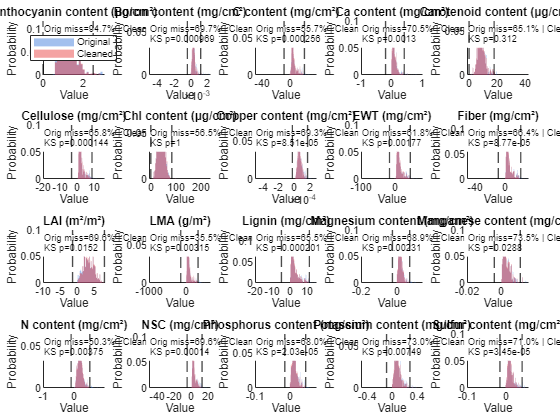

% colors
c_orig  = [0.20 0.45 0.85];
c_clean = [0.90 0.20 0.20];

X_orig  = table2array(traits_all_tbl);
X_clean = traits_all_clean;

figure; 
clf;
tiledlayout(4,5,"TileSpacing","compact","Padding","compact");

N_orig  = size(X_orig,1);
N_clean = size(X_clean,1);

for j = 1:trait_numbers
    x0 = X_orig(:,j);
    x1 = X_clean(:,j);
    % remove NaN
    x0 = x0(~isnan(x0));
    x1 = x1(~isnan(x1));

    % compute common binning
    x_all = [x0; x1];
    if isempty(x_all) || numel(unique(x_all))<=1
        minx = min([x_all; 0]); maxx = max([x_all; 1]);
        edges = linspace(minx-0.5, maxx+0.5, 5);
    else
        [~, edges] = histcounts(x_all, 'BinMethod','fd');
        if numel(edges) < 3
            edges = linspace(min(x_all), max(x_all), 11);
        end
    end

    nexttile; 
    hold on;
    h0 = histogram(x0, 'Normalization','probability', 'BinEdges',edges, ...
                   'EdgeColor','none', 'FaceColor',c_orig,  'FaceAlpha',0.45);
    h1 = histogram(x1, 'Normalization','probability', 'BinEdges',edges, ...
                   'EdgeColor','none', 'FaceColor',c_clean, 'FaceAlpha',0.45);
    xlabel('Value'); ylabel('Probability');
    title(string(trait_names{j}), 'Interpreter','none');

    % KS test
    miss0 = 1 - numel(x0)/N_orig;
    miss1 = 1 - numel(x1)/N_clean;
    pval = NaN;
    if ~isempty(x0) && ~isempty(x1)
        try
            [~, pval] = kstest2(x0, x1);
        catch
        end
    end

    % note
    note = sprintf('Orig miss=%.1f%% | Clean miss=%.1f%%\nKS p=%.3g', ...
                   miss0*100, miss1*100, pval);
    text(0.02, 0.95, note, 'Units','normalized', 'VerticalAlignment','top', ...
         'FontSize',7, 'BackgroundColor',[1 1 1 0.75], 'Margin',3);

    % ±3σ line
    mu0 = mean(x0,'omitnan');
    sd0 = std(x0,0,'omitnan');
    if ~isnan(sd0) && sd0 > 0
        xline(mu0 - 3*sd0, '--k', 'LineWidth',1);
        xline(mu0 + 3*sd0, '--k', 'LineWidth',1);
    end

    % legend
    if j == 1
        legend([h0 h1], {'Original','Cleaned'}, 'Location','best');
    end
    hold off;
end

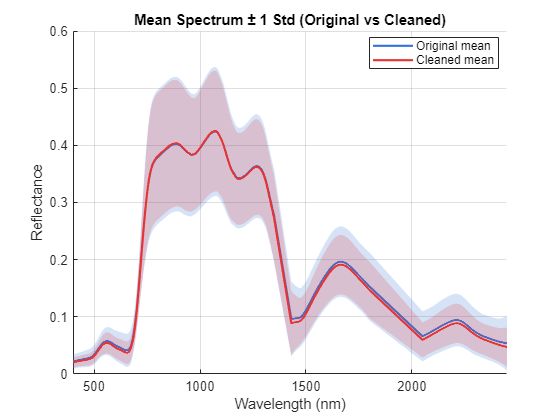

% spectra
mean_spec_orig  = mean(spectra_all, 1, 'omitnan');
std_spec_orig   = std( spectra_all, 0, 1, 'omitnan');
mean_spec_clean = mean(spectra_all_clean, 1, 'omitnan');
std_spec_clean  = std( spectra_all_clean, 0, 1, 'omitnan');

figure; 
clf; 
hold on;

% original
fill([wave_lengths_common fliplr(wave_lengths_common)], [mean_spec_orig-std_spec_orig,  fliplr(mean_spec_orig+std_spec_orig)], ...
     c_orig, 'FaceAlpha',0.20, 'EdgeColor','none');
p0 = plot(wave_lengths_common, mean_spec_orig,  'Color', c_orig,  'LineWidth',1.6);

% cleaned
fill([wave_lengths_common fliplr(wave_lengths_common)], [mean_spec_clean-std_spec_clean, fliplr(mean_spec_clean+std_spec_clean)], ...
     c_clean, 'FaceAlpha',0.20, 'EdgeColor','none');
p1 = plot(wave_lengths_common, mean_spec_clean, 'Color', c_clean, 'LineWidth',1.6);

xlabel('Wavelength (nm)'); ylabel('Reflectance');
xlim([min(wave_lengths_common) max(wave_lengths_common)]);
title('Mean Spectrum ± 1 Std (Original vs Cleaned)');
grid on;
legend([p0 p1], {'Original mean','Cleaned mean'}, 'Location','best');

hold off;

exploratory data analysis with PCA: explain variable correlations and visualize the PCs using biplots, loading plots; (! only on the X matrix - we are not looking at the response variable now)

% normalize
spectra_all_normalized = (spectra_all - mean_spectra_all)./std_spectra_all;

% PCA
[coeff, score, latent, tsquared, explained] = pca(spectra_all_normalized, 'Algorithm','svd');

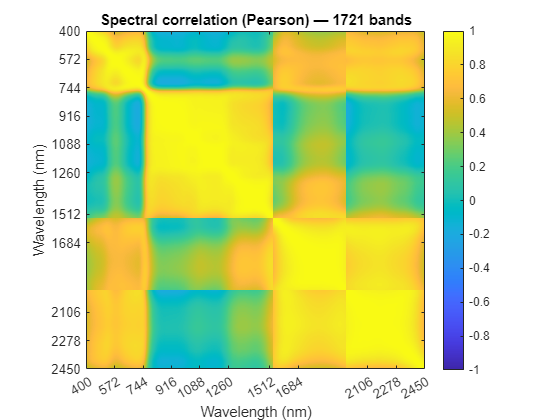


% correlation visualization

% sample if want to show less
selected_bands_numbers = wave_numbers_common;                             
if wave_numbers_common > selected_bands_numbers
    % sample
    idx = round(linspace(1, wave_numbers_common, selected_bands_numbers));
else
    idx = 1:wave_numbers_common;
end
spectra_all_normalized_s  = spectra_all_normalized(:, idx);
wave_lengths_s = wave_lengths_common(idx);

% correlation
corrType = 'Pearson';
R = corr(spectra_all_normalized_s, 'Type', corrType, 'Rows', 'pairwise');

% heatmap
figure; 
clf;
imagesc(wave_lengths_s, wave_lengths_s, R, [-1 1]); axis image; colormap(parula); colorbar;
xlabel('Wavelength (nm)'); ylabel('Wavelength (nm)');
title(sprintf('Spectral correlation (%s) — %d bands', corrType, numel(idx)));
set(gca,'XTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end), ...
        'YTick',wave_lengths_s(1:round(numel(wave_lengths_s)/10):end));

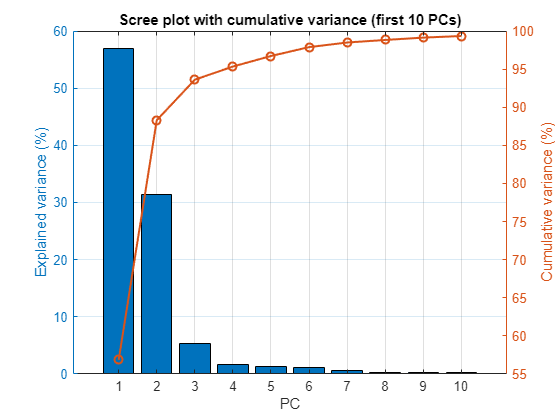

%% scree plot
figure(); 
clf;

yyaxis left
% first 10 principal component
bar(explained(1:10));                 
ylabel('Explained variance (%)');

yyaxis right
% cumulative variance
plot(cumsum(explained(1:10)), '-o', 'LineWidth',1.5);
ylabel('Cumulative variance (%)');

xlabel('PC');
title('Scree plot with cumulative variance (first 10 PCs)');
grid on;

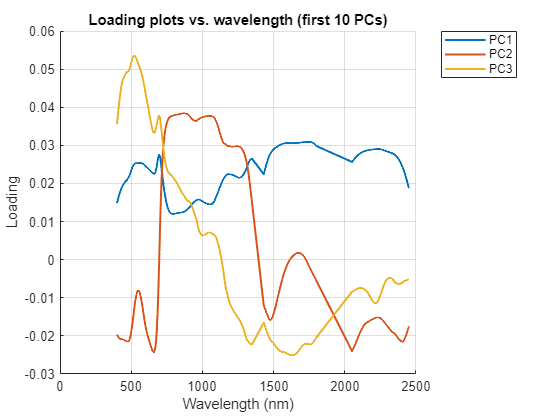

%% loading plots
figure();
clf; 
hold on;

% PC numbers wanted to show
numPC = 3;
colors = lines(numPC);

for k = 1:numPC
    plot(wave_lengths_common, coeff(:,k), 'LineWidth', 1.5, 'Color', colors(k,:));
end

xlabel('Wavelength (nm)'); 
ylabel('Loading');
legend("PC"+string(1:numPC), 'Location','bestoutside');
title('Loading plots vs. wavelength (first 10 PCs)');
grid on;